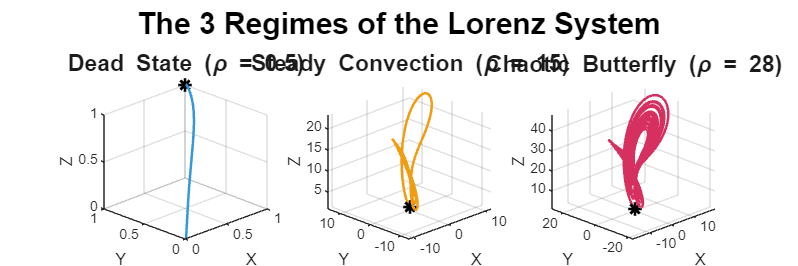


% LORENZ REGIMES (SEPARATE PLOTS)


clear; clc; close all;

% 1. Define Parameters
sigma = 10.0;
beta  = 8.0 / 3.0;
rho_values = [0.5, 15,28];


c_dead   = [0.20, 0.60, 0.86]; 
c_steady = [0.95, 0.61, 0.07]; 
c_chaos  = [0.84, 0.19, 0.38]; 
colors = {c_dead, c_steady, c_chaos};

titles = {
    'Dead State (\rho = 0.5)', ...
    'Steady Convection (\rho = 15)', ...
    'Chaotic Butterfly (\rho = 28)'
};

% 2. Initial Conditions
dt = 0.01;
t_span = 0:dt:50;      
init_cond = [1; 1; 1]; 


figure('Name', 'Lorenz Regimes Side-by-Side', 'Color', 'w', 'Position', [100, 250, 1500, 500]);


for i = 1:3
    rho = rho_values(i);
    
    lorenz_odes = @(t, s) [
        sigma * (s(2) - s(1));               
        s(1) * (rho - s(3)) - s(2);          
        s(1) * s(2) - beta * s(3)            
    ];

    [~, states] = ode45(lorenz_odes, t_span, init_cond);
    
   
    subplot(1, 3, i);
    hold on; grid on;
    

    plot3(states(:,1), states(:,2), states(:,3), 'Color', colors{i}, 'LineWidth', 1.5);
    

    plot3(init_cond(1), init_cond(2), init_cond(3), 'k*', 'MarkerSize', 8, 'LineWidth', 1.5);
    
    
    axis tight;
    xlabel('X'); ylabel('Y'); zlabel('Z');
    title(titles{i}, 'FontSize', 14, 'FontWeight', 'bold', 'Color', [0.1 0.1 0.1]);
    
    view(-45, 25); 
end

sgtitle('The 3 Regimes of the Lorenz System', 'FontSize', 18, 'FontWeight', 'bold');


drawnow; shg;